# Numerical Methods for Ordinary Differential Equations

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Differential equations show up in a wide range of contexts, from population modeling or engineering dynamics to pharmaco-kinetics or solving circuits. While some of these scenarios lend themselves to analytic, closed-form solutions, in many cases the solution must be approximated using a numerical method. In situations where the solution is unknown, it is important to have a clear idea of how much error may be present in a numerical solution. There are two types of error that can contribute to the total error of a numerical solution: roundoff error and discretization error. Recognizing roundoff error and controlling discretization error are required to implement numerical methods to solve differential equations.

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

## Numerical methods are commonly used for solving differential equations

If you think about it, [numerical integration](matlab: edit numericalIntegration.mlx) is already a method for solving differential equations of the form $\frac{dy}{dt} = f(t)$. In this script, we will consider the requirements to expand our methods to solve $\frac{dy}{dt} = f(t,y)$ and explore the usefulness of systems of differential equations. 

## Euler's Method

The simplest method of solving a first-order initial value problem is to start at a known value $(t_0,y_0)$ and attempt to follow a function $y(t)$ that is changing at a known rate given by the differential equation $\frac{dy}{dt}=f(t,y)$. Let's move with constant step size $\Delta t = h$. This information allows us to create a piecewise-linear function:

$y_{\text{approx}} = \begin{cases} y_0 + f(t_0,y_0)(t-t_0) & t_0 \leq t < t_0+h = t_1 \\ y_1 + f(t_1,y_1)(t-t_1) & t_1 \leq t < t_1+h = t_2\\ \vdots \\ y_n+f(t_n,y_n)(t-t_n) & t_n \leq t < t_n+h = t_{n+1} \end{cases}$,

where $y_n = y_{\text{approx}}(t_n)$.

It is more common to organize this into a table:


$$\matrix{k & t_k = t_{k-1}+h  & \;\;\;f(t_k,y_k) & \;\;y_{k+1} = y_k+f(t_k,y_k)h}$$



$$\pmatrix{ 0 & t_0 & f(t_0,y_0) & y_0+f(t_0,y_0)h \cr 1 & t_0+h & f(t_0+h,y_1) & y_1 + f(t_0+h,y_1)h \cr 2 & \;\;\;t_0+2h\;\;\; & f(t_0+2h,y_2) & y_2 + f(t_0+2h,y_2)h \cr \vdots & \vdots & \vdots & \vdots \cr n & t_0 + nh & f(t_0+nh,y_n) & y_n + f(t_0+nh,y_n)h}$$


**Exercise 1: Implement Euler's method to solve first-order initial value problems**

Write a function to implement Euler's method given a function handle, an initial value, a step size, and a number of steps to take.

edit eulerMethodDE.m

% % Uncomment this section to test your eulerMethodDE function
% errorAtEnd = TestEulerDECode(@eulerMethodDE,@(t,y) 2*t*sin(y),[0,1],10,0.5)

For comparison, with 

your solution should return `errorAtEnd = -0.8080` and look like:

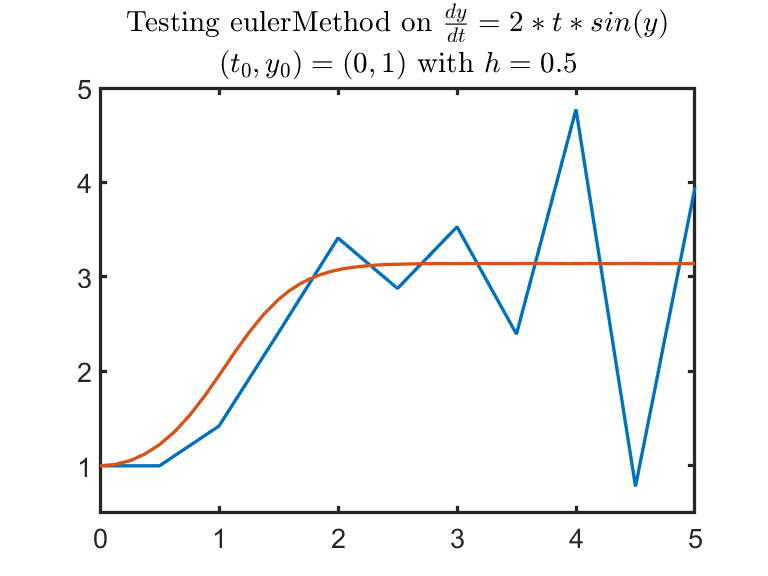

 **Try different values**

- Are there values of $h$ that result in good solutions for $\frac{dy}{dt} = 2t\sin(y)$ with $y(0)=1$ between $t=0$ and $t=5$? 

- With the function $\frac{dy}{dx} = 3y^2+2x-1$ and $(x_0,y_0)=(0,1)$, can you find a value for `h` that has an error of less than 0.01 from the true solution at $x=1$?

- What happens if you try different functions such as $\frac{dy}{dt} = \sin(y)$ or $\frac{dy}{dt} = e^y$ or $\frac{dy}{dt} = \frac{1}{t^2+y^2+1}$?

- How does your approximation change if you change the initial condition? What if you only change the $y_0$ value? Or only the $t_0$ value?

### Use Euler's method to investigate error

#### **Local error: a property of the method ** 

Assume we have a solution $y = \phi(t)$ to an initial value problem $\frac{dy}{dt} = f(y,t)$ with $y(t_0) = y_0$, and that $\phi(t)$ has a continuous second-order derivative. This means that at a point $t_n$, we know the solution $y_n = \phi(t_n)$ and the solution at $y_{n+1} = \phi(t_n+h)$, where $h = t_{n+1}-t_n > 0$. 

**Exercise 2:**

Using a Taylor series expansion of $y_{n+1} = \phi(t_{n+1}) = \phi(t_n+h)$ and the Euler approximation $y_{n}^{\text{approx}}(t_{n+1}) = y_n + f(y_n,t_n)h$, compute the theoretical error 

$\text{local error} = y_{n+1}-y_{n}^{\text{approx}}(t_{n+1}) \leq Rh^k$, 

where $R$ is a constant that can depend on the function $\phi$ and value $t_n$. 

Hint: You may want to review the error calculation presented in the [Numerical Integration script](matlab:open('./NumericalIntegration.mlx')). 

**Solution: **

Show your calculations here. You can test your result with the following code using $k =$ `kLocal`.

% Replace 0 with your result
kLocal = 0;
CheckError(kLocal,"forwardEuler","local")

#### **Global error: a property of the method**

To reach a value $y_n$ from $y_0$ requires $n$ steps, each of which will contribute a portion of local error. 

**Exercise 3: **

Explain why the theoretical global error is

$\text{global error} = y_{n}-y_0^{\text{approx}}(t_{n}) \leq Mh^{k}$,

where $y_0^{\text{approx}}(t_{n}) = y_0^{\text{approx}}(t_{n-1}) + f(y_0^{\text{approx}}(t_{n-1}),t_{n-1})h$ with $y_0^{\text{approx}}(t_0) = y_0$ and $M$ is a constant that can depend on $\phi$ as well as $t_{n}$ and $t_0$. 

**Solution: **

Show your calculations here. You can test your result with the following code using $k =$ `kGlobal`.

kGlobal = 0;
CheckError(kGlobal,"forwardEuler","global")

#### **Roundoff error: a property of the implementation **

Implementation of a method in computer hardware and software contributes to roundoff error.  Roundoff error accumulates whenever the exact value of a number and the value that the computer can store differ. 

**Exercise 4:**

To observe roundoff error, create a table of errors using your implementation of the Euler method to solve

$\frac{dy}{dt} = t\sin(y)$    with $y(0)=1$,

for $y(1)$. How small can $h$ be before the roundoff error overwhelms the error computation?

The symbolic analytic solution `ySol` is computed by the following code:

syms y(t)
ode = diff(y,t)==t*sin(y);
cond = y(0)==1;
ySol(t) = dsolve(ode,cond)

Hint 1: You may want to review the error calculation presented in the Numerical Integration script. 

**Solution:**

% %% Write your solution here


### Euler's backward difference method

**Exercise 5: **

What changes are necessary to implement an Euler backward difference method using the relation

$y_n = y_{n-1} + hf(y_n,t_n)$?

a) If $\frac{dy}{dt} = f(y,t)$ is linear?

b) If $\frac{dy}{dt} = f(y,t)$ is nonlinear?

 **Reflect**. 

- What are the main challenges for the Euler backward difference method?

- Considering the error of this method, would you ever want to use it for a real problem?

### Improving on the Euler forward difference method

Consider the solution $y= \phi(t)$ to an initial value problem $\frac{dy}{dt} = f(y,t)$ with $y(t_0)=y_0$. Expressing relationships through integration, we have:


$$\phi(t_n+h) = \phi(t_n)+\int_{t_n}^{t_n+h}f(\phi(t),t)\; dt.$$


This formulation shows that the Euler forward difference method uses a left-endpoint approximation to the integral. The Euler backward difference method uses a right-endpoint approximation to the integral. We know other simple integral approximations, though. 

**Exercise 6:**

Design an explicit numerical method that uses the trapezoidal rule to approximate the integral. Check the error of your method. 

% % You may want to start by opening and saving a copy of your eulerMethodDE into a new
% % file called improveEulerMethod.m
edit eulerMethodDE

## Runge-Kutta Method

While the forward Euler method is used for its simplicity and ease of implementation, the most common workhorse of numerical methods for solving differential equations is the four-step Runge-Kutta method:

$y_{n+1} = y_n + h\left(\frac{k_{n1} + 2k_{n2}+2k_{n3}+k_{n4}}{6}\right)$     where                                                      

$k_{n1} = f(t_n,y_n)$                      is the slope at the left endpoint                                 

$k_{n2} = f\left(t_n+\frac{h}{2},y_n+\frac{h}{2}k_{n1}\right)$  is the estimated slope at the midpoint                      

$k_{n3} = f\left(t_n+\frac{h}{2},y_n + \frac{h}{2}k_{n2}\right)$  is an improved estimate of the slope at the midpoint

$k_{n4} = f(t_n+h,y_n+hk_{n3})$     is an estimate of the slope at the right endpoint       

                                           (using the best midpoint slope calculation)

**Exercise 7:** 

Implement the four-step Runge-Kutta method.

edit rk4.m

To test your implementation, uncomment this section to compare your output to the built-in Runge-Kutta solver `ode45`.

% % Set parameters and input values
% f = @(t,y) (y^2+2*t*y)/(3+t^2);
% tspan = [0 2];
% y0 = 0.5;
% n = 40;
% 
% % Run and compare the output
% [tOut,yOut] = rk4(f,tspan,y0,n);
% [tTest,yTest] = ode45(f,tspan,y0);
% plot(tOut,yOut,tTest,yTest)
% title("Comparing rk4 and ode45 output")
% legend(["rk4" "ode45"],"Location","best")
% xlabel("t")
% ylabel("y")
% error = yOut(end)-yTest(end)

 **Reflect**. 

- Do you know another name for this method when applied to approximate integrals, $\displaystyle y = \int_{a}^{b}f(t)\; dt$?

## Rapidly varying results can require special methods

When a solution varies quickly, this may not be tracked very well by fixed step size numerical methods without using an impractically small step size. One type of problem where this is evident has solutions that vary slowly in some regions but quickly nearby. They are called stiff equations. 

### Example: Modeling a flame

Consider the example of combustion. If you light a candle, the flame grows rapidly from nothing to a critical size governed by the point at which the amount of oxygen available on the surface equals the amount of oxygen consumed by combustion in the interior. A simple model of this interaction is: 

$\frac{dy}{dt} = y^2-y^3$,                $y(0) = \delta$

where $y$ is a length parameter, so $y^2$ measures surface area and $y^3$ measures volume. The parameter $\delta$ is very small, as it is modeling the length parameter of the initial spark. 

  **Try**. 

- Run the example code below with different values for `numSteps`. How many steps do you have to take before the solution matches the values created by the variable-step solver `ode23s`?

- How much time does it take to run your `eulerMethodDE` solver for large numbers of steps (e.g., `1e6, 1e7, 1e8`)? 

dydt = @(t,y) y.^2-y.^3;
y0 = 1e-6;
tfinal = 2/y0;
opts = odeset("RelTol",1e-4);
numSteps = 1e6;
tic
[myT,myY] = eulerMethodDE(dydt,[0 y0],numSteps,tfinal/numSteps);
toc
plot(myT,myY,'-o',"SeriesIndex",1,"LineWidth",2)

tic
[t,y] = ode23s(dydt,[0 tfinal],y0,opts);
toc
hold on
plot(t,y,'-o',"SeriesIndex",2)
hold off
title("Comparing Solutions")
legend(["Euler Method" "ode23s"],"Location","best")

 **Reflect**.

- How much time do you think it would take to run your solver with `numSteps = 1e9`?

- By comparing the plots, what do you think `ode23s` is doing differently that lets it compute the correct answer more quickly?

- Can you convince yourself that the solution plotted by `ode23s` is correct? Why or why not?

## Solving Systems of Differential Equations

You may have noticed that all of our numerical methods for solving differential equations are built for first-order differential equations. Higher-order differential equations are generally expressed as a system of first-order differential equations and then solved.

Consider a standard second-order equation, 

        $F = ma$,                          $(\star)$

which would generally be expressed as $F = m\frac{d^2x}{dt^2}$ or even $\frac{d^2x}{dt^2} = \frac{F}{m}$. If the force is $F = \frac{1}{2}\rho C_D A v^2 - mg$,         

where $\frac{1}{2}\rho C_D A v^2$ is the high-velocity drag force of an object of cross-sectional area $A$ moving at velocity $v$ through a liquid of density $\rho$ with drag coefficient $C_D$ and $g$ is the acceleration due to gravity we can simplify equation $(\star)$ to:


$$\frac{d^2x}{dt^2} = \frac{\beta}{m}\left(\frac{dx}{dt}\right)^2-g,$$


where $\beta = \frac{1}{2}\rho C_D A$ and $v = \frac{dx}{dt}$. 

As this equation is nonlinear, it may be convenient to consider a numerical solution method. This can be written as a pair of first-order differential equations:


$$\frac{dx}{dt} = v$$
               

$\frac{dv}{dt} = -\frac{\beta}{m}v^2+g$,

by taking advantage of the relationship that $\frac{d}{dt}\left(\frac{dx}{dt}\right) = \frac{d^2x}{dt^2}$. 

Step 1: Create a function `MotionDE` that expresses the system of differential equations. 

function dxdt = MotionDE(t,y,beta,m,g)
% MotionDE takes two variables, t and y, and three parameters, beta, m, and
% g and it returns a vector dxdt consisting of the velocity and
% acceleration at time t

% For ease of reference, name the components of y


% Express the system of differential equations in terms of the parameters,
% independent variable, and dependent variables. It is not dxdt = y.
dxdt = y;
end

Step 2: Use [`ode45`](matlab: doc ode45) to solve the differential equation and plot the results.

m = 68;     % kg for a human
rho = 1.2;  % kg/m^3 for air
C = 1.05;   % estimated drag coefficient
A = 0.59;   % m^2 estimated cross-sectional area
g = 9.81;   % m/s^2
y0 = 1800;  % m initial height
v0 = 0;     % m/s initial velocity
beta = 0.5*rho*C*A;
tspan = [0 40];
[t,y] = ode45(@(t,y) MotionDE(t,y,beta,m,g),tspan,[y0;v0]);
plot(t,y(:,1),"-","SeriesIndex",1)
xlabel("Time from jump (s)")
ylabel("Elevation (m)")
title("Modeling a Skydive")
plot(t,-y(:,2),"-","SeriesIndex",2)
hold on

Calculate the theoretical terminal velocity and plot it together with the velocity curve for your skydiver. Do they agree? 

% Theoretical terminal velocity
tVelTheory = sqrt(2*m*g/(rho*C*A));
plot(t,tVelTheory*ones(size(t)),"--","SeriesIndex",3)
hold off
title("Modeling a Skydive")
xlabel("Time from jump (s)")
ylabel("Downward velocity (m/s)")
u = symunit;
terminalVelocity = y(end,2)*u.m/u.sec;
terminalVelocity = unitConvert(unitConvert(terminalVelocity,u.km),u.h);
[tVel,velUnits] = separateUnits(terminalVelocity);
format short
tVel = -round(double(tVel),2);
subtitle("Terminal velocity: "+tVel+" km/hr")

 **Reflect**.

- What other scenarios could this equation model?  

- How much do the results depend on the parameters we chose? 

- How would you model a skydiver who opened a parachute after 30 seconds?

## Further Explorations

Work through the pendulum example to explore how numerically approximating solutions to differential equations can facilitate the use of more realistic models of a system. 

open PendulumModels.mlx

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Test Functions

function out = TestEulerDECode(EulerMethodDE,f,init,n,h) 
[tOut,yOut] = ode45(f,[init(1) init(1)+n*h],init(2));
[xVals,yVals] = EulerMethodDE(f,init,n,h);
plot(xVals,yVals);
hold on
plot(tOut,yOut)
hold off
fStr = func2str(f);
idx = regexp(fStr,'[)]')+1;
title("Testing Euler Method on $\frac{dy}{dt} = "+fStr(idx(1):end)+"$","Interpreter","latex")
subtitle("$(t_0,y_0) = ("+init(1)+","+init(2)+")$ with $h="+h +"$","Interpreter","latex")
out = double(yOut(end)-yVals(end));
end

function CheckError(k,method,type)
if type == "local"
    shift = 0;
elseif type == "global"
    shift = -1;
end
switch method
    case "forwardEuler"
        val = 2;
    case "backwardEuler"
        val = 2;
    case "heun"
        val = 3;
    case "rk"
        val = 5;
end
if k == 0
    disp("The default answer is not correct. Please enter the value you computed.")
elseif k == val+shift
    disp("Your solution is correct.")
else
    disp("Your solution is incorrect. Please try again.")
end
end
%#ok<*INUSD>
%#ok<*INUSL>
%#ok<*DEFNU>